# **Classify Human Electrocardiogram (ECG) Signals**

**Digital Signal Processing**

________________________________________________________________________________________

**Submitted by****:**

- **Vedant Sanjay Chavan**

**Under the guidance of****: **

- **Prof. Dr. Markus Stichler**

________________________________________________________________________________________

### **Contents:**

1.Introduction

2.Generating Training data

- Short Time Fourier Transformation (STFT)  

- Continuous wavelet Transformation (CWT)

3.Training for CWT

- GoogleNet

- SqueezeNet

- AlexNet

4.Training for STFT 

- GoogleNet

- SqueezeNet

- AlexNet

5.Test and validate the Networks( Confusion Charts)

- Confusion chart  for CWT

- Confusion chart  for STFT

6.Apply the Networks to given ECG Signal

- Continuous wavelet Transformation (CWT) -GoogleNet, SqueezeNet, AlexNet

- Short time Fourier Transformation (STFT)-GoogleNet, SqueezeNet AlexNet

7.[Test Data](matlab:open('/ECG_TestingData.mlx'))

# Introduction

In general people can be divided in three groups:

- **persons with cardiac arrhythmia (ARR)**

- **persons with congestive heart failure (CHF), and**

- **persons with normal sinus rhythms (NSR).** 

The goal of this PStA is to classify human electrocardiogram (ECG) signals using the Short Time Fourier Transformation and the Continuous Wavelet Transform (CWT) and deep convolutional neural networks (CNNs). The resulting CNNs are used to classify the given ECG signal to ARR, CHF, and NSR, respectively. 

# Generating the Training Data

**The training and test data are publicly available from **[**PhysioNet**](https://physionet.org/)

load("ECGData.mat")
data1 = ECGData.Data;
labels = ECGData.Labels;

The given data contains 96 ARR signals,30 CHF signals and 66 NSR signals. So, for training the CNN we take equal number of signals i.e. **30 each**.

data3=[data1(1:30,:);data1(97:126,:);data1(127:156,:)]; %30 signals each
labels3=[labels(1:30,:);labels(97:126,:);labels(127:156,:)];
Fs1=128

Data is generated over the signal length of 10 heartbeats or **(10*Sampling rate)**

signalLength1=10*Fs1

###  Short Time Fourier Transformation (STFT)

% Check for directories %
if ~exist('Data_STFT_images', 'dir')

Fs1 = 128

    mkdir('Data_STFT_images');
    if ~exist('Data_STFT_images/ARR', 'dir')

signalLength1 = 1280

        mkdir('Data_STFT_images/ARR');
    end
    if ~exist('Data_STFT_images/CHF', 'dir')
        mkdir('Data_STFT_images/CHF');
    end
    if ~exist('Data_STFT_images/NSR', 'dir')
        mkdir('Data_STFT_images/NSR');
    end
end

% After making required directories, Start generating training Data %
cnt=0;
%The for loop iterates over each signal and... 
% ...generates images approximately 1530 images for each category.
for i=1:length(data3(:,1))    
    temp=1;
    for j=1:(length(data3(1,:))/signalLength1)
        
        fig = figure('Visible', 'off');
        spectrogram(resample(data3(i,temp:signalLength1*j),10,1),hann(16),8,512, ...
            signalLength1,'MinThreshold',-100,'yaxis');
        % Upsampling by factor of 10; hann window of length 16;
        % 8 number of samples to overlap; 512 is length of FFT;
        % signalLength specifices signal length 
        axis off; % to remove axis and other legends
        colorbar off; % turnoff colour bar
        set(gcf, 'Units', 'pixels', 'Position', [0 0 512 512]);
        set(gca, 'Position', [0 0 1 1]);
        temp=signalLength1+temp;
        imgLoc = fullfile('Data_STFT_images/',char(labels3(i)));
        imFileName = strcat(char(labels3(i)),'_',num2str(cnt),'.jpg');
        % saving file to the location
        saveas(gcf,fullfile(imgLoc,imFileName)) 
        cnt=cnt+1;
        close(fig); 
        progress = j/(length(data3(1,:))/signalLength1);        
    end   
end

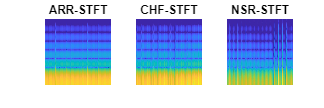

img1 = imread('Data_STFT_images/ARR/ARR_1.jpg');
img2 = imread('Data_STFT_images/CHF/CHF_1530.jpg');
img3 = imread('Data_STFT_images/NSR/NSR_3060.jpg');
fig=figure('Position',[0 0 1800 600]);
% plotting ARR
subplot(1,3,1)
imshow(img1);
title('ARR-STFT');
% plotting STFT
subplot(1,3,2)
imshow(img2);
title('CHF-STFT');
% plotting NSR
subplot(1,3,3)
imshow(img3);
title('NSR-STFT');

### Continuous wavelet Transformation (CWT)

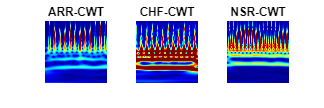

% Check for directories %
if ~exist('Data_CWT_images', 'dir')
    mkdir('Data_CWT_images');
    if ~exist('Data_CWT_images/ARR', 'dir')
        mkdir('Data_CWT_images/ARR');
    end
    if ~exist('Data_CWT_images/CHF', 'dir')
        mkdir('Data_CWT_images/CHF');
    end
    if ~exist('Data_CWT_images/NSR', 'dir')
        mkdir('Data_CWT_images/NSR');
    end
end

% After making required directories, Start generating training Data %
fb = cwtfilterbank('SignalLength',signalLength1, ...
    'SamplingFrequency',Fs1,'VoicesPerOctave',12);

cnt=0;
%The for loop iterates over each signal and... 
% ...generates images approximately 1530 images for each category.
for i=1:length(data3(:,1))    
    temp=1;
    for j=1:(length(data3(1,:))/signalLength1)
        %extracting data according to signal length
        sig = data3(i,temp:signalLength1*j);
        [cfs,frq] = wt(fb,sig);
        %im2uint8 Convert image to 8-bit unsigned integers
        img = ind2rgb(im2uint8(rescale(abs(cfs))),jet(128));
        temp=signalLength1+temp;

        imgLoc = fullfile('Data_CWT_images/',char(labels3(i)));
        imFileName = strcat(char(labels3(i)),'_',num2str(cnt),'.jpg');
        % saving file to the location
        imwrite(imresize(img,[512 512]),fullfile(imgLoc,imFileName)) 
        cnt=cnt+1;
             
    end   
end

img1 = imread('Data_CWT_images/ARR/ARR_1.jpg');
img2 = imread('Data_CWT_images/CHF/CHF_1530.jpg');
img3 = imread('Data_CWT_images/NSR/NSR_3060.jpg');
fig=figure('Position',[0 0 1800 600]);
% plotting ARR
subplot(1,3,1)
imshow(img1);
title('ARR-CWT');
% plotting STFT
subplot(1,3,2)
imshow(img2);
title('CHF-CWT');
% plotting NSR
subplot(1,3,3)
imshow(img3);
title('NSR-CWT');

# Training for Continuous Wavelet Transform (CWT)

## **GoogleNet- CWT**

- GoogLeNet is a convolutional neural network that is 22 layers deep. 

- GoogLeNet requires RGB images of size 224-by-224-by-3

#### Loading the data in matlab for training

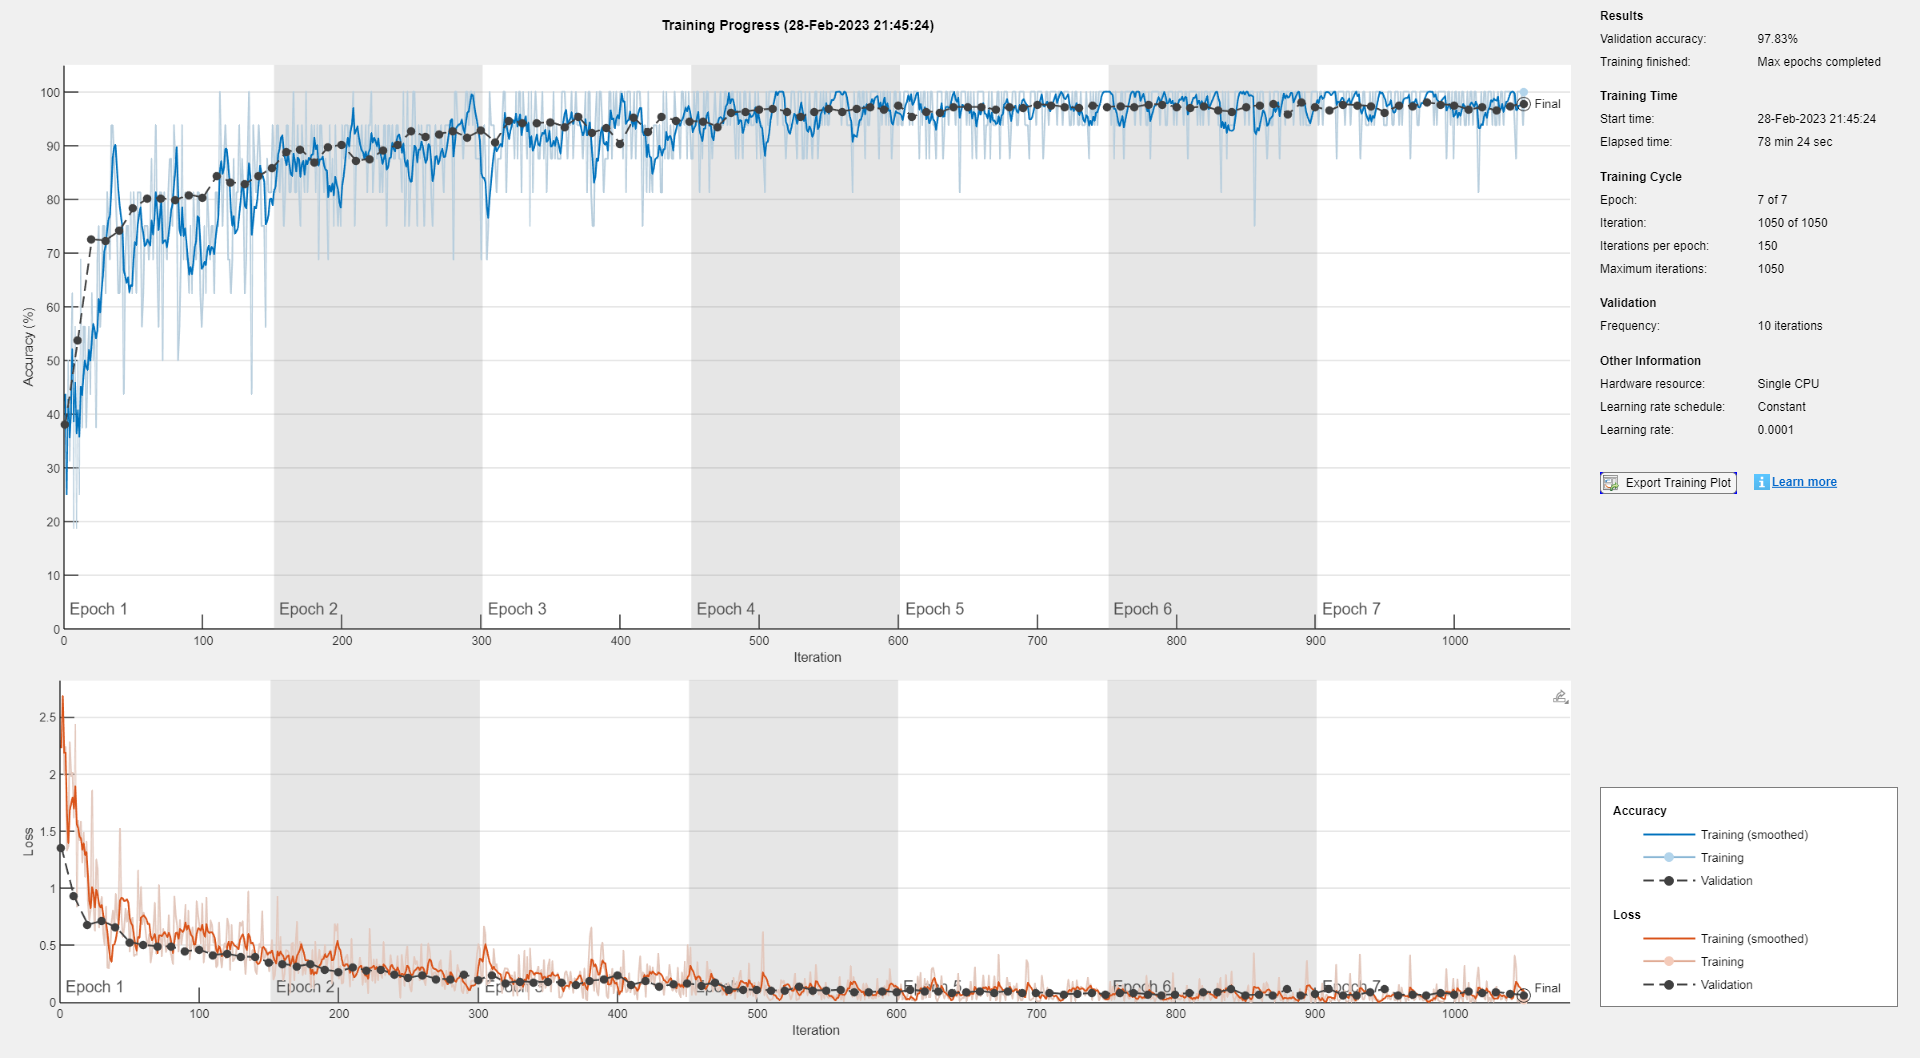

Data_path = 'Data_CWT_images/'
allImages = imageDatastore(fullfile(Data_path),...
    'IncludeSubfolders',true,...

    'LabelSource','foldernames');
rng default
% Dividing Training and Validation data
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);
disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

#### Designing CNN for prediction of three classes- ARR,CHF,NSR

net = googlenet; %loads googlenet

Data_path = 'Data_CWT_images/'

Extract the layer graph from the network

lgraph = layerGraph(net);

To prevent overfitting, a dropout layer is used. A dropout layer randomly sets input elements to zero with a given probability. The default probability is 0.5. Replace the final dropout layer in the network, `'pool5-drop_7x7_s1'`, with a dropout layer of probability 0.6

newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

Setting the fully connected layer to have the same size as number of classes (ARR,CHF,NSR)

numClasses = numel(categories(imgsTrain.Labels)); 

Number of training images: 2400


% categories : reads labeled folder and provides total number of classes

Number of validation images: 600


Replace the fully connected layer 'loss3-classifier' with a new fully connected layer with the number of filters equal to the number of classes

newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer)

Replace the classification layer with a new one without class labels as `trainNetwork` automatically sets the output classes of the layer at training time

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

Resizing training and validation data to 224-by-224-by-3. Augmented image datastore automatically resizes the existing RGB images

Trainimgs_ = augmentedImageDatastore([224 224],imgsTrain);
Valimgs_ = augmentedImageDatastore([224 224],imgsValidation);

Setting the parameters of the Model

options = trainingOptions('sgdm',...
    'MiniBatchSize',16,...
    'MaxEpochs',7,...
    'InitialLearnRate',0.0001,...
    'Shuffle','every-epoch', ...
    'ValidationData',Valimgs_,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Training the Model

GN_CWT_wts = trainNetwork(Trainimgs_,lgraph,options);
save GN_CWT_wts   %Saving mat files so that weights can be used later for predictions

## **SqueezeNet- CWT**

- The idea behind designing SqueezeNet, was to create a smaller neural network with fewer parameters (hence lesser computations and lesser memory requirements and low inference time) that can easily fit into memory devices and can more easily be transmitted over a computer network.

-  SqueezeNet is a deep CNN whose architecture supports images of size 227-by-227-by-3.

#### Loading the data in matlab for Training

clear all
close all
Data_path = 'Data_CWT_images/'
allImages = imageDatastore(fullfile(Data_path),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);
disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

#### Designing CNN for prediction of three classes- ARR,CHF,NSR

net2 = squeezenet;

Extract the layer graph from the network

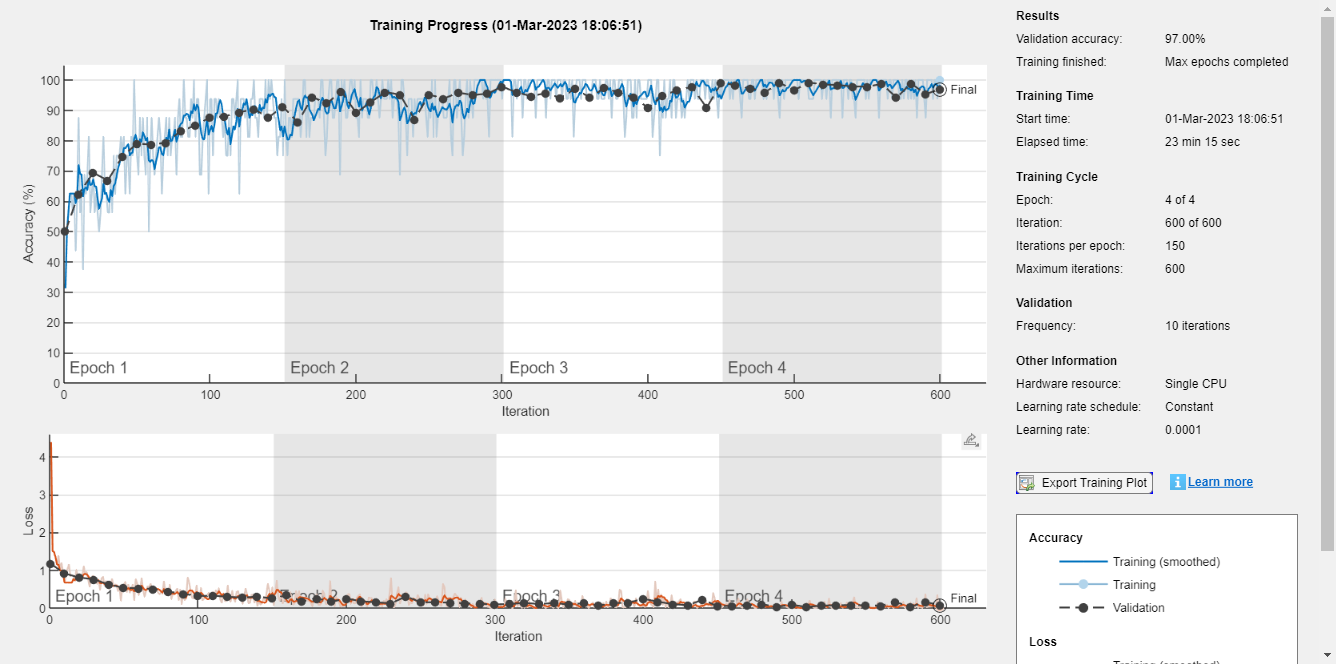

lgraphSqz = layerGraph(net2);

tmpLayer = lgraphSqz.Layers(end-5);

To prevent overfitting, a dropout layer is used. A dropout layer randomly sets input elements to zero with a given probability. The default probability is 0.5. Replace the final dropout layer in the network, `'tmpLayer'`, with a dropout layer of probability 0.6

newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');

Data_path = 'Data_CWT_images/'

lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newDropoutLayer);

Setting the fully connected layer to have the same size as number of classes (ARR,CHF,NSR)

numClasses = numel(categories(imgsTrain.Labels));

tmpLayer = lgraphSqz.Layers(end-4);

Replace the fully connected layer 'loss3-classifier' with a new fully connected layer with the number of filters equal to the number of classes

newLearnableLayer = convolution2dLayer(1,numClasses, ...

Number of training images: 2400


        'Name','new_conv', ...

Number of validation images: 600


        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newLearnableLayer);

tmpLayer = lgraphSqz.Layers(end);

Replace the classification layer with a new one without class labels as `trainNetwork` automatically sets the output classes of the layer at training time

newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newClassLayer);

Resizing training and validation data to 227-by-227-by-3. Augmented image datastore automatically resizes the existing RGB images

Trainimgs_ = augmentedImageDatastore([227 227],imgsTrain);
Valimgs_ = augmentedImageDatastore([227 227],imgsValidation);

Setting the Parameters of the Model

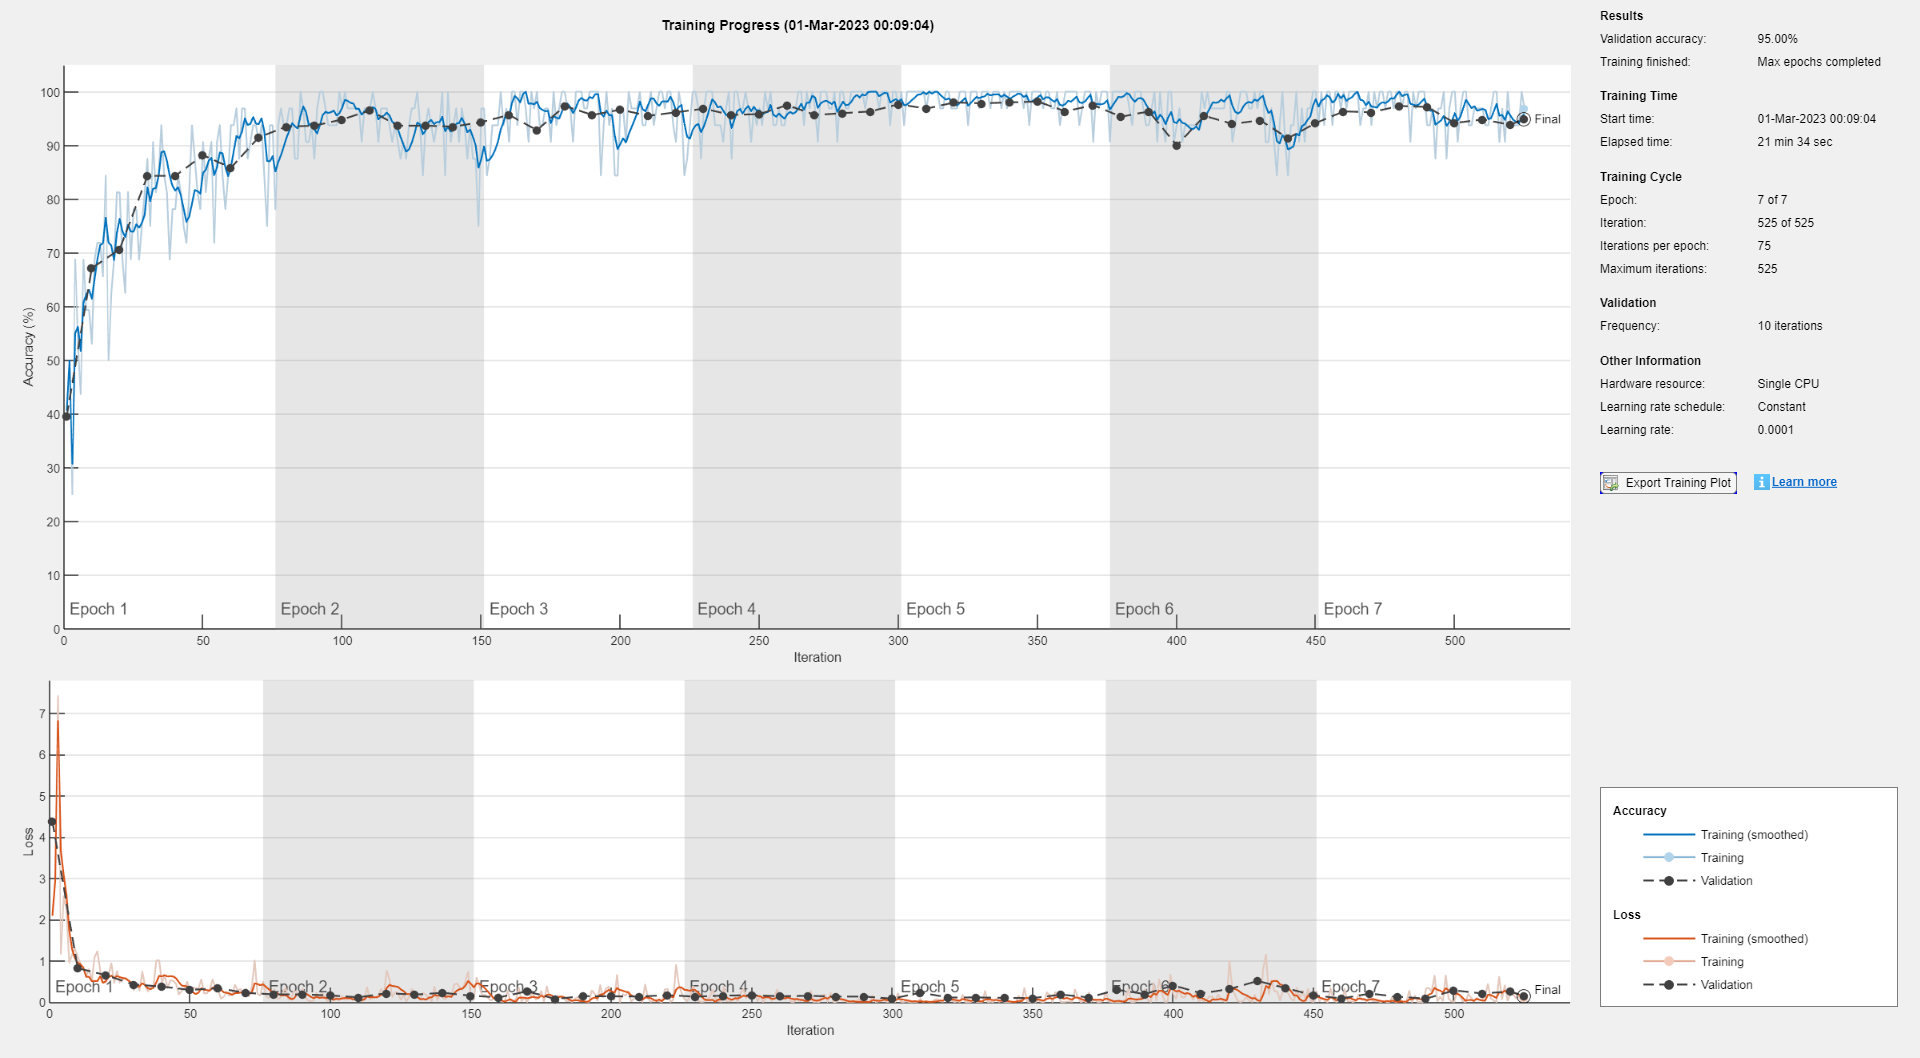

ilr = 0.0001;
miniBatchSize = 16;
maxEpochs = 4;
valFreq =10;

opts = trainingOptions('adam',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'Shuffle','every-epoch', ...
    'ValidationData',Valimgs_,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');


rng default

Training the Model

SN_CWT_wts = trainNetwork(Trainimgs_,lgraphSqz,opts);

Data_path = 'Data_STFT_images/'

save SN_CWT_wts   %Saving mat files so that weights can be used later for predictions

## **AlexNet- CWT**

- AlexNet is a convolutional neural network that is 8 layers deep; out of which 5 are convolutional layers and 3 are fully connected layers. 

- An important feature of the AlexNet is the use of ReLU(Rectified Linear Unit) Nonlinearity.

- The network has an image input size of 227-by-227.

#### Loading the data in Matlab for Training

Data_path = 'Data_CWT_images/'
allImages = imageDatastore(fullfile(Data_path),...
    'IncludeSubfolders',true,...

Number of training images: 2400


    'LabelSource','foldernames');

Number of validation images: 600



rng default
% Dividing Training and Validation data
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);
disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

#### Designing CNN for prediction of three classes- ARR,CHF,NSR

net3 = alexnet;
% Input size for network
net3.Layers(1).InputSize;

Replace Final Layers for prediction of ARR,CHF,NSR

Layerstransfer = net3.Layers(1:end-3); 

Setting the fully connected layer to have the same size as number of classes (ARR,CHF,NSR)

numClasses = numel(categories(imgsTrain.Labels));
% changing last 3 layers of Alexnet with fulluconected layer, softmax and
% classification layer

Increasing the weight learn factor and Bias learn factor of fully connected layer to make the model learn faster

alxnet_layers = [Layerstransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

Resizing training and validation data to 227-by-227-by-3. Augmented image datastore automatically resizes the existing RGB images

Trainimgs_ = augmentedImageDatastore([227 227],imgsTrain);
Valimgs_ = augmentedImageDatastore([227 227],imgsValidation);

Setting the Training Parameters of the Model

alxnet_options = trainingOptions('adam','MiniBatchSize',32,'MaxEpochs',7, ...
    "InitialLearnRate",0.0001,'Shuffle','every-epoch', ...
    'ValidationData',Valimgs_,'ValidationFrequency',10, ...
    'Verbose',1,'ExecutionEnvironment','auto', ...
    'Plots','training-progress');

Training the Model

AN_CWT_wts = trainNetwork(Trainimgs_,alxnet_layers,alxnet_options);
save AN_CWT_wts %Saving mat files so that weights can be used later for predictions

# Training for Short Time Fourier Transformation (STFT)

## **GoogleNet- STFT**

#### Loading data in matlab for training

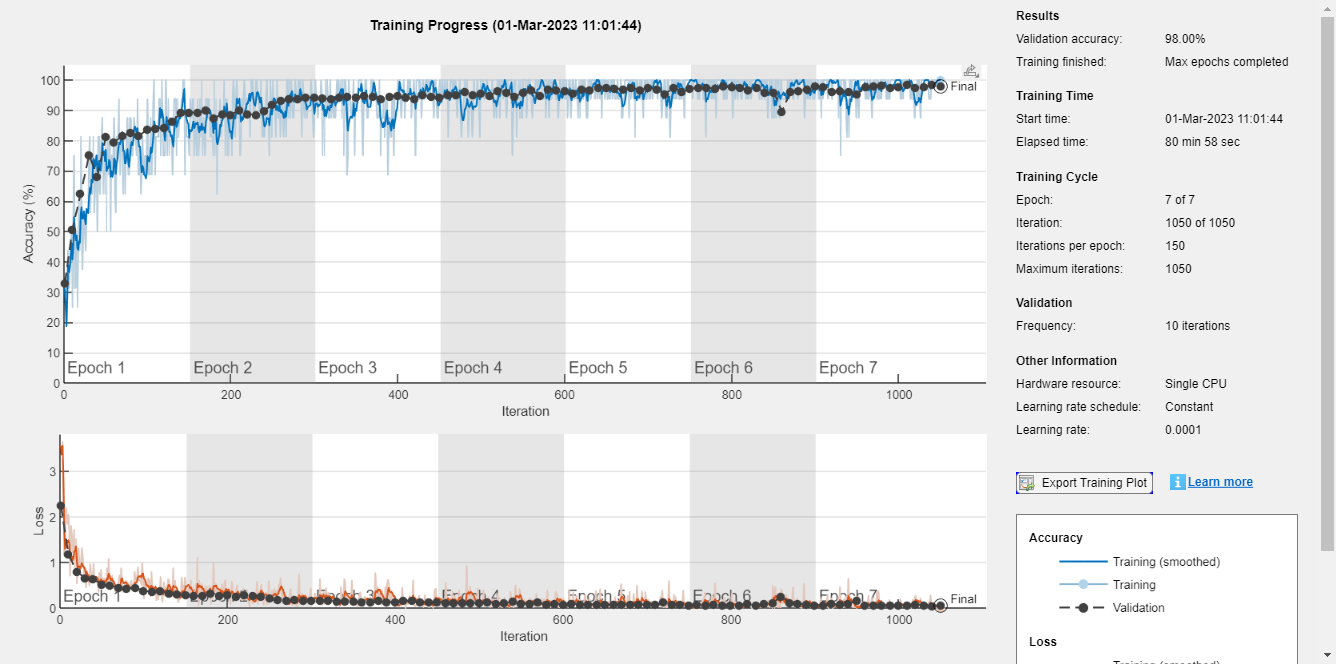

Data_path = 'Data_STFT_images/'

allImages = imageDatastore(fullfile(Data_path),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default

Data_path = 'Data_STFT_images/'

[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);
disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

#### Designing CNN for prediction of three classes- ARR,CHF,NSR

net = googlenet;

Extract the layer graph from the network

lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);

Number of training images: 2400


To prevent overfitting, a dropout layer is used. A dropout layer randomly sets input elements to zero with a given probability. The default probability is 0.5. Replace the final dropout layer in the network, `'pool5-drop_7x7_s1'`, with a dropout layer of probability 0.6

newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');

Number of validation images: 600


lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

Setting the fully connected layer to have the same size as number of classes (ARR,CHF,NSR)

numClasses = numel(categories(imgsTrain.Labels));
% categories : reads labeled folder and provides total number of classes

Replace the fully connected layer 'loss3-classifier' with a new fully connected layer with the number of filters equal to the number of classes

newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);

Number of Layers: 68


lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer)

Replace the classification layer with a new one without class labels as `trainNetwork` automatically sets the output classes of the layer at training time

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

Resizing training and validation data to 224-by-224-by-3. Augmented image datastore automatically resizes the existing RGB images

Trainimgs_ = augmentedImageDatastore([224 224],imgsTrain);
Valimgs_ = augmentedImageDatastore([224 224],imgsValidation);

Setting the parameters of the Model

options = trainingOptions('sgdm',...
    'MiniBatchSize',16,...
    'MaxEpochs',7,...
    'InitialLearnRate',0.0001,...
    'Shuffle','every-epoch', ...
    'ValidationData',Valimgs_,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Training the Model

GN_STFT_wts = trainNetwork(Trainimgs_,lgraph,options);
save GN_STFT_wts %Saving mat files so that weights can be used later for predictions

## **SqueezeNet - STFT**

#### Loading the data in Matlab for Training

Data_path = 'Data_STFT_images/'
allImages = imageDatastore(fullfile(Data_path),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);
disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

#### Designing CNN for prediction of three classes- ARR,CHF,NSR

net2 = squeezenet;       

Extract the layer graph from the network

lgraphSqz = layerGraph(net2);
disp(['Number of Layers: ',num2str(numel(lgraphSqz.Layers))])
lgraphSqz.Layers(end-5:end)
tmpLayer = lgraphSqz.Layers(end-5);


To prevent overfitting, a dropout layer is used. A dropout layer randomly sets input elements to zero with a given probability. The default probability is 0.5. Replace the final dropout layer in the network, `'tmpLayer'`, with a dropout layer of probability 0.6

newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newDropoutLayer);

Setting the fully connected layer to have the same size as number of classes (ARR,CHF,NSR)

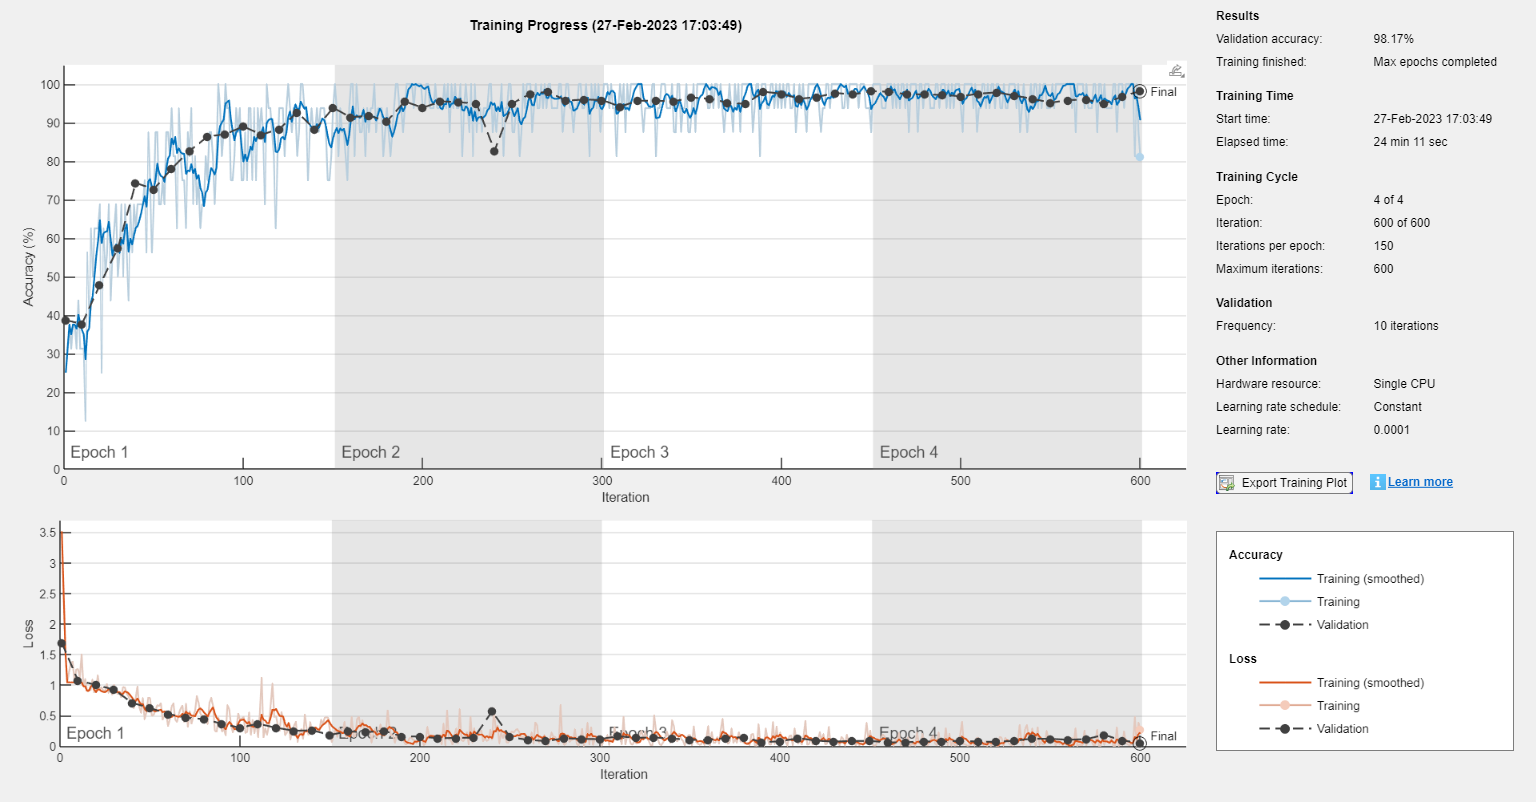

numClasses = numel(categories(imgsTrain.Labels));

% categories : reads labeled folder and provides total number of classes

Replace the classification layer with a new one without class labels as `trainNetwork` automatically sets the output classes of the layer at training time

tmpLayer = lgraphSqz.Layers(end-4);

Data_path = 'Data_STFT_images/'


newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newLearnableLayer);


Number of training images: 2400


tmpLayer = lgraphSqz.Layers(end);

Number of validation images: 600


Replace the classification layer with a new one without class labels as `trainNetwork` automatically sets the output classes of the layer at training time

newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newClassLayer);

Resizing training and validation data to 224-by-224-by-3. Augmented image datastore automatically resizes the existing RGB images

Trainimgs_ = augmentedImageDatastore([227 227],imgsTrain);
Valimgs_ = augmentedImageDatastore([227 227],imgsValidation);

Setting the Training parameters of the Model

ilr = 0.0001;
miniBatchSize = 16;
maxEpochs = 4;
valFreq = 10;

opts = trainingOptions('adam',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'Shuffle','every-epoch', ...
    'ValidationData',Valimgs_,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default

Training the Model

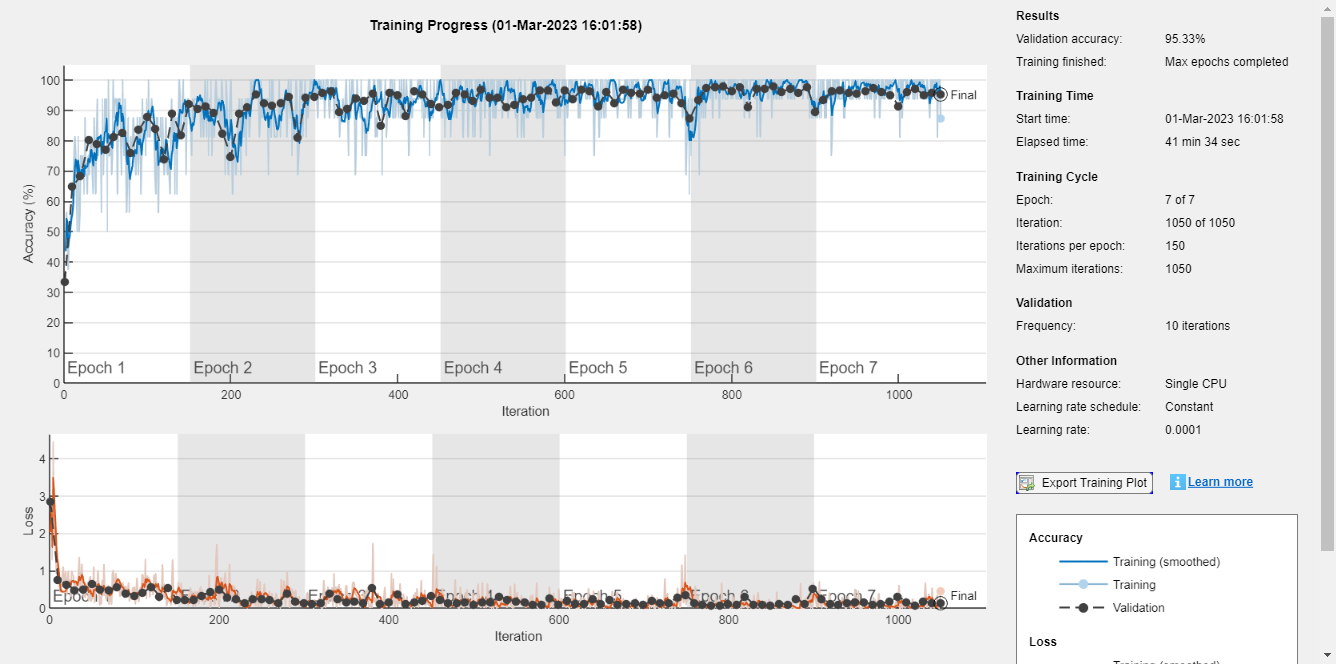

SN_STFT_wts = trainNetwork(Trainimgs_,lgraphSqz,opts);

save SN_STFT_wts %Saving mat files so that weights can be used later for predictions

## **AlexNet- STFT**

#### Loading the data in Matlab for Training

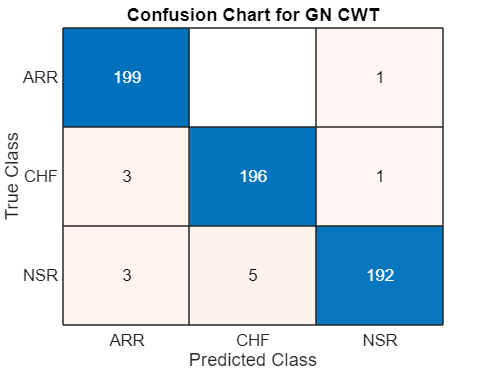

Data_path = 'Data_STFT_images/'
allImages = imageDatastore(fullfile(Data_path),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');


rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');

GoogleNet Accuracy: 97.8333%


disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);
disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

#### Designing CNN for prediction of three classes- ARR,CHF,NSR

net3 = alexnet;
% Input size for network
net3.Layers(1).InputSize;
% loading all layers except last 3

Replace Final Layers for prediction of ARR,CHF,NSR

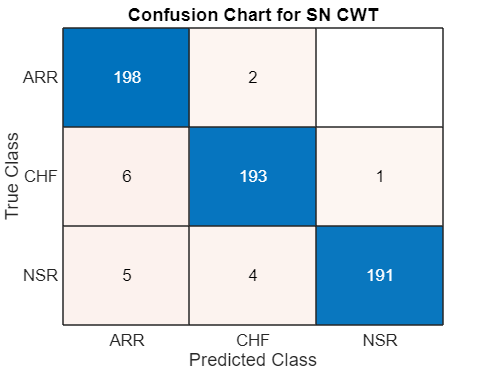

Layerstransfer = net3.Layers(1:end-3); 

Setting the fully connected layer to have the same size as number of classes (ARR,CHF,NSR)

numClasses = numel(categories(imgsTrain.Labels));
% changing last 3 layers of Alexnet with fulluconected layer, softmax and

SqueezeNet Accuracy: 97%


% classification layer

Increasing the weight learn factor and Bias learn factor of fully connected layer to make the model learn faster

alxnet_layers = [Layerstransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

Resizing training and validation data to 227-by-227-by-3. Augmented image datastore automatically resizes the existing RGB images

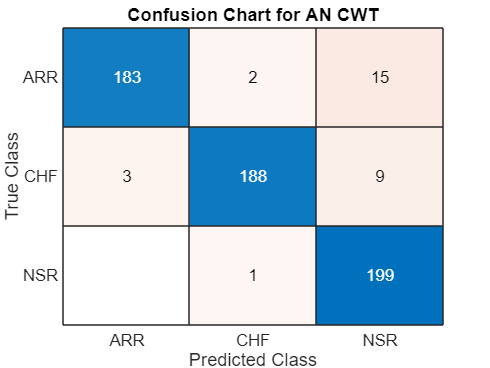

Trainimgs_ = augmentedImageDatastore([227 227],imgsTrain);

Valimgs_ = augmentedImageDatastore([227 227],imgsValidation);

Setting the Training Parameters of the Model

alxnet_options = trainingOptions('adam','MiniBatchSize',16,'MaxEpochs',7, ...

AlexNet Accuracy: 95%


    "InitialLearnRate",0.0001,'Shuffle','every-epoch', ...
    'ValidationData',Valimgs_,'ValidationFrequency',10, ...
    'Verbose',1,'ExecutionEnvironment','auto', ...
    'Plots','training-progress');

Training the Model

AN_STFT_wts = trainNetwork(Trainimgs_,alxnet_layers,alxnet_options);
save AN_STFT_wts  %Saving mat files so that weights can be used later for predictions

________________________________________________________________________________________

# **Test and validate the Networks -- Confusion Charts**

## **Confusion chart for CWT**

________________________________________________________________________________________

**Plotting confusion chart for GoogleNet**

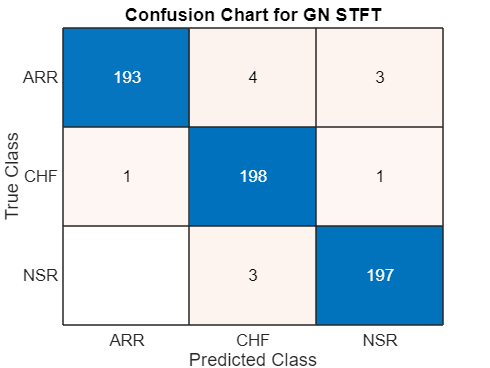

load ('GN_CWT_wts.mat');
[YPred,~]= classify(GN_CWT_wts,Valimgs_);
accuracyGNCWT = mean(YPred==imgsValidation.Labels);

confusionchart(imgsValidation.Labels, YPred)
title('Confusion Chart for GN CWT')

GoogleNet Accuracy: 98%


figure;
disp(['GoogleNet Accuracy: ',num2str(accuracyGNCWT*100),'%'])

________________________________________________________________________________________

**Plotting confusion chart for SqueezeNet**

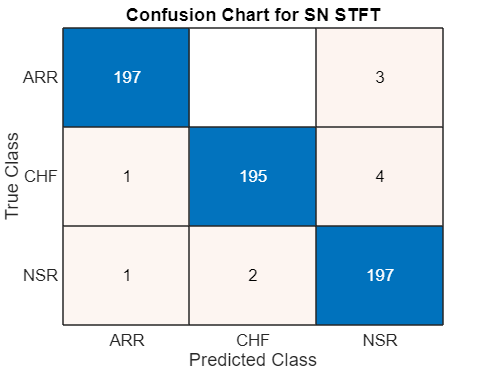

load ('SN_CWT_wts.mat');
[YPred,~]= classify(SN_CWT_wts,Valimgs_);
accuracySNCWT = mean(YPred==imgsValidation.Labels);
confusionchart(imgsValidation.Labels, YPred)
title('Confusion Chart for SN CWT')

figure;
disp(['SqueezeNet Accuracy: ',num2str(accuracySNCWT*100),'%'])

SqueezeNet Accuracy: 98.1667%


________________________________________________________________________________________

**Plotting confusion chart for AlexNet**

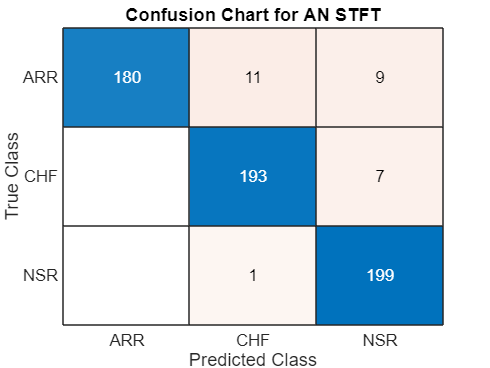

load ('AN_CWT_wts.mat');
[YPred,~]= classify(AN_CWT_wts,Valimgs_);
accuracyANCWT = mean(YPred==imgsValidation.Labels);
confusionchart(imgsValidation.Labels, YPred)
title('Confusion Chart for AN CWT')

figure;
disp(['AlexNet Accuracy: ',num2str(accuracyANCWT*100),'%'])

AlexNet Accuracy: 95.3333%


________________________________________________________________________________________

## **Confusion chart  for STFT**

________________________________________________________________________________________

**Plotting confusion chart for GoogleNet**

load ('GN_STFT_wts.mat');
[YPred,~]= classify(GN_STFT_wts,Valimgs_);
accuracyGNSTFT = mean(YPred==imgsValidation.Labels);
confusionchart(imgsValidation.Labels, YPred)
title('Confusion Chart for GN STFT')
figure;
disp(['GoogleNet Accuracy: ',num2str(accuracyGNSTFT*100),'%'])

________________________________________________________________________________________

**Plotting confusion chart for SqueezeNet**

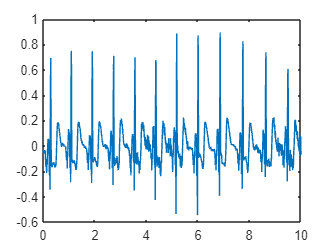

load ('SN_STFT_wts.mat');

[YPred,~]= classify(SN_STFT_wts,Valimgs_);
accuracySNSTFT = mean(YPred==imgsValidation.Labels);
confusionchart(imgsValidation.Labels, YPred)
title('Confusion Chart for SN STFT')
figure;
disp(['SqueezeNet Accuracy: ',num2str(accuracySNSTFT*100),'%'])

________________________________________________________________________________________

**Plotting confusion chart for AlexNet**

load ('AN_STFT_wts.mat');
[YPred,~]= classify(AN_STFT_wts,Valimgs_);
accuracyANSTFT = mean(YPred==imgsValidation.Labels);
confusionchart(imgsValidation.Labels, YPred)
title('Confusion Chart for AN STFT')
figure;
disp(['AlexNet Accuracy: ',num2str(accuracyANSTFT*100),'%'])

________________________________________________________________________________________

#### Observations for confusion charts and accuracy:

Looking at the confusion charts and accuracy, we can conclude that STFT with these three models (GoogleNet, SqueezeNet, and AlexNet) is performing better than CWT with these models. GoogleNet gives better results in both cases (STFT and CWT). The reason might be the complex architecture that makes networks learn minute features, followed by Squeezenet and AlexNet.

In our project, the hyperparameters were set after several training iterations, largely by adjusting the epochs, learning rate, and batch size. The reason for the low number of epochs is because with a higher epoch, the model was overfitting, resulting in poor accuracy. It should be noted that changing the training data or the preprocessing data differently may result in different results.

# **Apply the Networks to given ECG Signal**

**Given is the following given ECG signal  **      

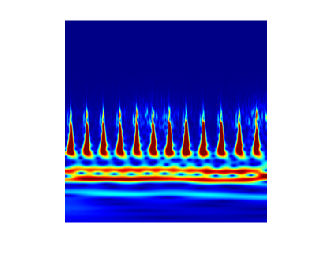

% load ecg signal 
ecg =load('ecg.mat');
% Graphical Output


% Time Signal
t = (0:length(ecg.data(1:80000))-1)/ecg.fs;
plot(t,ecg.data(1:80000))

## Continuous Wavelet Transformation (CWT)

Preprocessing the given signal considering sampling rate of 8000 and Signal length of 80000

load ('ecg.mat');
data=data';

Prediction for GoogleNet:  NSR 

fb = cwtfilterbank('SignalLength',80000, ...

Probability of:  87.53 %

    'SamplingFrequency',8000,'VoicesPerOctave',12);
sig = data(1:80000);
[cfs,frq] = wt(fb,sig);
%im2uint8 Convert image to 8-bit unsigned integers
img = ind2rgb(im2uint8(rescale(abs(cfs))),jet(128));

Prediction for SqueezeNet:  NSR 

img=imresize(img,[512 512]);

Probability of:  68.49 %

filename=strcat('testCWT.jpg');
imwrite(img,fullfile(filename))
img1=imresize(img,[256 256]);
figure;
imshow(img1)

Prediction for AlexNet:  NSR 

#### GoogleNet

img= imresize(img,[224 224]);

Probability of:  63.43 %

load('GN_CWT_wts.mat')
[YPred1,probs1] = classify(GN_CWT_wts,img);
fprintf('Prediction for GoogleNet:  %s ',YPred1)
fprintf('Probability of:  %0.02f %%',max(probs1*100))

#### SqueezeNet

img= imresize(img,[227 227]);
load('SN_CWT_wts.mat')
[YPred3,probs3] = classify(SN_CWT_wts,img);
fprintf('Prediction for SqueezeNet:  %s ',YPred3)
fprintf('Probability of:  %0.02f %%',max(probs3*100))

#### AlexNet

img= imresize(img,[227 227]);
load('AN_CWT_wts.mat')
[YPred2,probs2] = classify(AN_CWT_wts,img);
fprintf('Prediction for AlexNet:  %s ',YPred2)
fprintf('Probability of:  %0.02f %%',max(probs2*100))

## Short time Fourier Transformation (STFT)

Preprocessing the given signal considering sampling rate of 8000 and Signal length of 80000

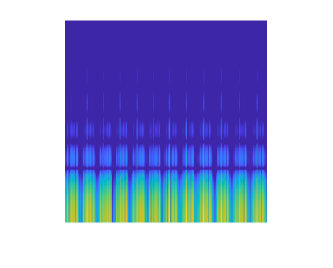

load ('ecg.mat');
data=data';

fig = figure('Visible', 'off');
spectrogram(resample(data(1:80000),10,1),hann(16),8,512, ...
80000,'MinThreshold',-100,'yaxis');

axis off; % to remove axis and other legends
colorbar off; % turnoff colour bar
set(gcf, 'Units', 'pixels', 'Position', [0 0 512 512]);
set(gca, 'Position', [0 0 1 1]);
imFileName = strcat('testSTFT.jpg');
% saving file to the location
saveas(gcf,fullfile(imFileName))

Prediction for GoogleNet:  NSR 

close(fig); 

Probability of:  95.51 %

img1=imread('testSTFT.jpg');
img1=imresize(img1,[256 256]);
figure;
imshow(img1)

#### GoogleNet

img=imread('testSTFT.jpg');
img= imresize(img,[224 224]);

Prediction for SqueezeNet:  NSR 

load('GN_STFT_wts.mat')

Probability of:  65.17 %

[YPred1,probs1] = classify(GN_STFT_wts,img);
fprintf('Prediction for GoogleNet:  %s ',YPred1)
fprintf('Probability of:  %0.02f %%',max(probs1*100))

#### SqueezeNet

img=imread('testSTFT.jpg');
img= imresize(img,[227 227]);
load('SN_STFT_wts.mat')

Prediction for AlexNet:  NSR 

[YPred3,probs3] = classify(SN_STFT_wts,img);

Probability of:  94.46 %

fprintf('Prediction for SqueezeNet:  %s ',YPred3)
fprintf('Probability of:  %0.02f %%',max(probs3*100))

#### AlexNet

img=imread('testSTFT.jpg');
img= imresize(img,[227 227]);
load('AN_STFT_wts.mat')
[YPred2,probs2] = classify(AN_STFT_wts,img);
fprintf('Prediction for AlexNet:  %s ',YPred2)
fprintf('Probability of:  %0.02f %%',max(probs2*100))

#### **Observation from Prediction:**

Following is the comparison between preprocessed training image and the preprocessed image generated for testing signal.

- It can be seen that the STFT images are pretty similar to each other.That's why we are getting high probabilities for STFT predictions.

- The reason behind the low probability of predictions for CWTis likely due to the sampling rate, as the sampling rate for training data signals was 128 Hz and the sampling rate for a given signal for testing was 8000 Hz. Hence resulting in a slightly different prediction image, which results in low probability.

- If we get more training data with a varying sampling rate, then such issues can be avoided and better results can be achieved.

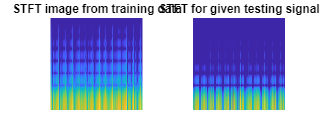

figure('Position',[100 100 1600 700]);

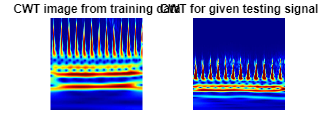

subplot(1,2,1)
imshow(imresize(imread('Data_STFT_images/NSR/NSR_3895.jpg'),[256 256]))
title('STFT image from training data')
subplot(1,2,2)
imshow(imresize(imread('testSTFT.jpg'),[256 256]))
title('STFT for given testing signal')
figure('Position',[100 100 1600 700]);

subplot(1,2,1)
imshow(imresize(imread('Data_CWT_images/NSR/NSR_4473.jpg'),[256 256]))
title('CWT image from training data')
subplot(1,2,2)
imshow(imresize(imread('testCWT.jpg'),[256 256]))
title('CWT for given testing signal')

**Testing data on different signals can be done **[**here**](matlab:open('/ECG_TestingData.mlx'))** or open TestingData.mlx file**